**Lozano Garcia Eduardo Alejandro **

**Pantography**

**A) **

A series of 6 images for different pathologies and normal walking senarios are given. This images were collected using pressure sensores. For the first task, interpolate the images in order to obtain a "fluid video" The interpolation should be done pixel by pixel in each RGB Channel.

** A.1) Load Images: **

We will load the images that exists as a Rank-3 Tensors R in (height,widht,channel) into a Rank-4 Tensor R in (height,widht,channel,id) 

clear all; close all; clc;

%%% METADATA %%%%
root   = "..//imagenes//";                % Root directory where images are stored
images = ["atypical","typical","mid"];  % List of names of images
NumPhotos = 6;                          % Number of Original images for each Class
Height    = 320;                        % Desired Height
Width     = 240;                        % Desired Width 

%%% LOAD IMAGES IN A TENOSR %%%%
for i=1:1:length(images)                % Iterate over size of image class
    eval(sprintf('A%d = zeros(%d,%d,3,%d);;', i,Height,Width,NumPhotos )); % Create Tensor to store images
    for j=1:1:6                                                            % Iterate over image number 
           path = root  + images(i) + "0" + string(j) + ".jpeg";            % Recunstruct image path
           A = imread(path);                                               % Load Image
           A = imresize(A,[Height, Width]);                                      % Resize image 
           eval(sprintf('A%d(:,:,:,%d)= uint8(A) ;', i,j));                      % Save image in tensor
    end
 end

**A.2) Interpolate Images:**

In this next code we will make the interpolation of each pixel.


%%%% Interpolation of Images %%%%
Time = [0,1,2,3,4,5];  % Time stamp for original Images 
Tfinal = 5;
ti=0:0.1:Tfinal;             % Interpolation Time 
[null,steps]=size(ti)

null = 1

steps = 51


%%% Interpolation for A1 Tensor (Atypical Examples %%%
for i=1:Height       % Iterate over image Height 
    for j=1:Width    % Iterate over width
        for c=1:3    % Iterate over Channel
            %%% Rearange Tensor in order to use MATLAB'S interp1 function
            aux2=[A1(i,j,c,1),A1(i,j,c,2),A1(i,j,c,3),A1(i,j,c,4),A1(i,j,c,5),A1(i,j,c,6)];
            %%% Interpolate images through time
            A1_inter(i,j,c,:)= uint8(interp1(Time,double(aux2),ti,'pchip'));
        end
    end
end

%%% Interpolation for A2 Tensor (Typical Examples) %%%
for i=1:Height      % Iterate over image Height 
    for j=1:Width   % Iterate over width
        for c=1:3   % Iterate over Channel
            %%% Rearange Tensor in order to use MATLAB'S interp1 function
            aux2=[A2(i,j,c,1),A2(i,j,c,2),A2(i,j,c,3),A2(i,j,c,4),A2(i,j,c,5),A2(i,j,c,6)];
            %%% Interpolate images through time
            A2_inter(i,j,c,:)= uint8(interp1(Time,double(aux2),ti,'pchip'));
        end
    end
end

%%% Interpolation for A2 Tensor (Mid Examples) %%%
for i=1:Height      % Iterate over image Height 
    for j=1:Width   % Iterate over width
        for c=1:3   % Iterate over Channel
            %%% Rearange Tensor in order to use MATLAB'S interp1 function
            aux2=[A3(i,j,c,1),A3(i,j,c,2),A3(i,j,c,3),A3(i,j,c,4),A3(i,j,c,5),A3(i,j,c,6)];
            %%% Interpolate images through time
            A3_inter(i,j,c,:)= uint8(interp1(Time,double(aux2),ti,'pchip'));
        end
    end
end

**A.3) Show Video of interpolations**

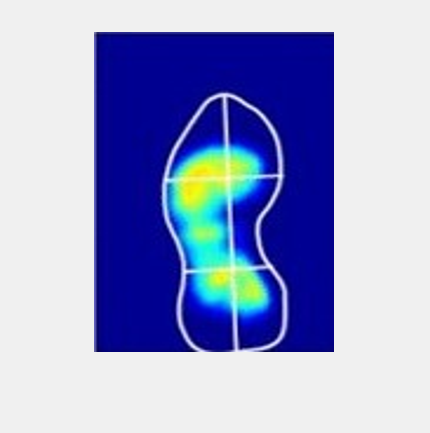

%% ATYPICAL 
figure(1)
set(gcf,'Name','Atypical','Visible','on')
for k=1:steps
imshow(uint8(A1_inter(:,:,:,k))) % muestra la imagen
end

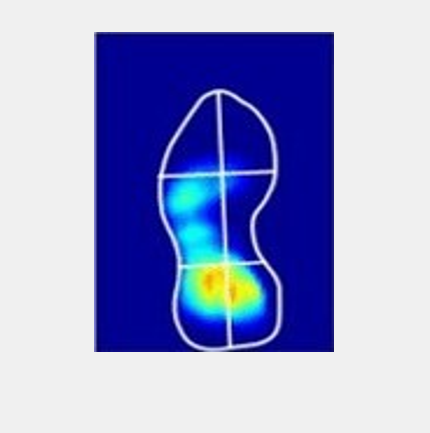

%% TYPICAL
figure(2)
set(gcf,'Name','Typical','Visible','on')
for k=1:steps
imshow(uint8(A2_inter(:,:,:,k))) % muestra la imagen
end

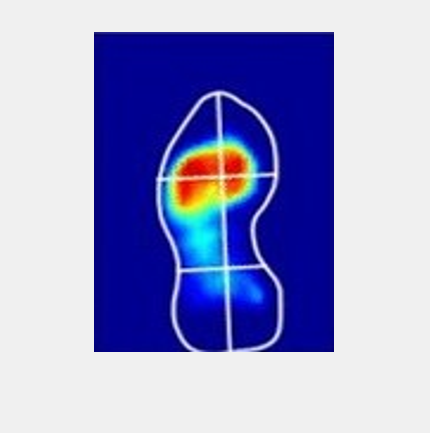


%% MID
figure(3)
set(gcf,'Name','Mid','Visible','on')
for k=1:steps
imshow(uint8(A3_inter(:,:,:,k))) % muestra la imagen
end 

**B) **

Perform an algorithm that can fractionate the images in order to obtain a representative rectangle for each of the sections shown in the image at point A. Determine the grayscale equivalent of each section and obtain its average value from the gray values. Plot the average gray values for each of the six sections of the image.

**B.1) Create Six Bounding Boxes to represent different zones:**

% coordenadas para analizar de la sección 1
X1=66;
Y1=66;
X2=119;
Y2=140;
% coordenadas para de la sección 2
X3=123;
Y3=66;
X4=173;
Y4=141;
% coordenadas para de la sección 3
X5=64;
Y5=156;
X6=123;
Y6=233;
% coordenadas para de la sección 4
X7=127;
Y7=153;
X8=159;
Y8=231;
% coordenadas para de la sección 5
X9=83;
Y9=244;
X10=126;
Y10=316;
% coordenadas para de la sección 6
X11=132;
Y11=244;
X12=177;
Y12=299;

%%%%%

**ATYPICAL**

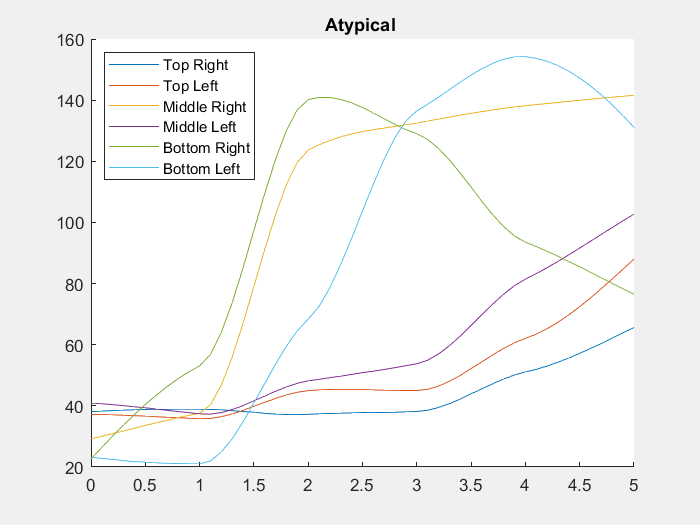

[w,h,c,I] = size(A1_inter);
TL1 = [];
TR1 = [];
ML1 = [];
MR1 = [];
BL1 = [];
BR1 = [];
for i=1:1:I
    A_gray = rgb2gray(uint8(A1_inter(:,:,:,i)));
    TL1(:,end+1)=average_energy(A_gray(Y1:Y2,X1:X2));
    TR1(:,end+1)=average_energy(A_gray(Y3:Y4,X3:X4));
    ML1(:,end+1)=average_energy(A_gray(Y5:Y6,X5:X6));
    MR1(:,end+1)=average_energy(A_gray(Y7:Y8,X7:X8));
    BL1(:,end+1)=average_energy(A_gray(Y9:Y10,X9:X10));
    BR1(:,end+1)=average_energy(A_gray(Y11:Y12,X11:X12));
    
end

figure(4)
set(gcf,'Name','Average Energy Through Time','Visible','on')
hold on;
plot(ti,TL1)
hold on;
plot(ti,TR1)
hold on;
plot(ti,ML1)
hold on;
plot(ti,MR1)
hold on;
plot(ti,BL1)
hold on;
plot(ti,BR1)  
title("Atypical ")
legend({'Top Right','Top Left','Middle Right','Middle Left','Bottom Right','Bottom Left'},'Location','northwest');

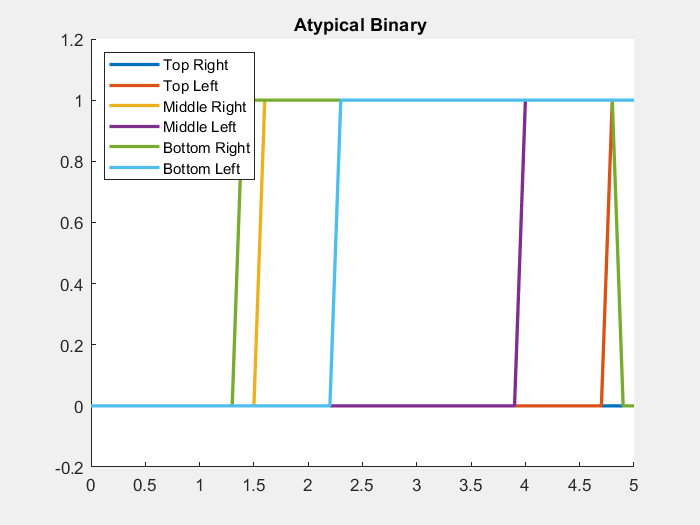

TH = 80;
%% Logic values for  analog reads
TL1b=  TL1 > TH;
TR1b = TR1 > TH;
ML1b = ML1 > TH;
MR1b = MR1 > TH;
BL1b = BL1 > TH;
BR1b = BR1 > TH;
%% load time series for simulink  %%
TL1bs=  timeseries(TL1b,ti);
TR1bs = timeseries(TR1b,ti);
ML1bs = timeseries(ML1b,ti);
MR1bs = timeseries(MR1b,ti);
BL1bs = timeseries(BL1b,ti);
BR1bs = timeseries(BR1b,ti);

figure(5)
set(gcf,'Name','Average Energy Through Time binary','Visible','on')
hold on;
plot(ti,TL1b,'LineWidth',2)
hold on;
plot(ti,TR1b,'LineWidth',2)
hold on;
plot(ti,ML1b,'LineWidth',2)
hold on;
plot(ti,MR1b,'LineWidth',2)
hold on;
plot(ti,BL1b,'LineWidth',2)
hold on;
plot(ti,BR1b,'LineWidth',2)
title("Atypical Binary ")
ylim([-0.2 1.2])
legend({'Top Right','Top Left','Middle Right','Middle Left','Bottom Right','Bottom Left'},'Location','northwest');

**TYPICAL**

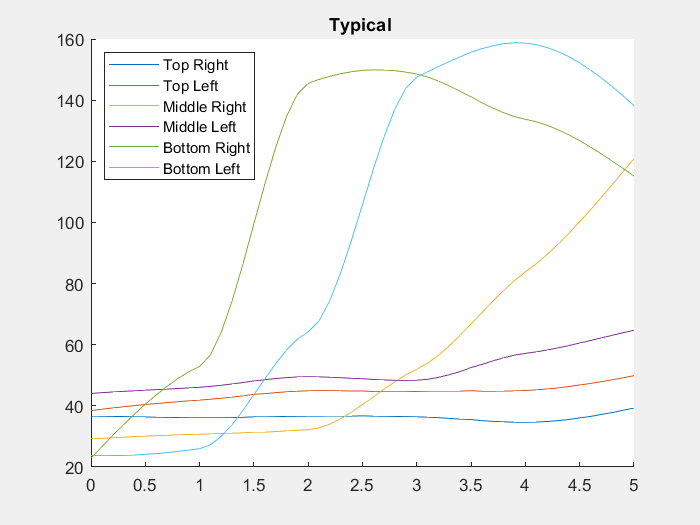


[w,h,c,I] = size(A2_inter);
TL2 = [];
TR2 = [];
ML2 = [];
MR2 = [];
BL2 = [];
BR2 = [];
for i=1:1:I
    A_gray = rgb2gray(uint8(A2_inter(:,:,:,i)));
    TL2(:,end+1)=average_energy(A_gray(Y1:Y2,X1:X2));
    TR2(:,end+1)=average_energy(A_gray(Y3:Y4,X3:X4));
    ML2(:,end+1)=average_energy(A_gray(Y5:Y6,X5:X6));
    MR2(:,end+1)=average_energy(A_gray(Y7:Y8,X7:X8));
    BL2(:,end+1)=average_energy(A_gray(Y9:Y10,X9:X10));
    BR2(:,end+1)=average_energy(A_gray(Y11:Y12,X11:X12));
    
end

figure(6)
set(gcf,'Name','Average Energy Through Time','Visible','on')
hold on;
plot(ti,TL2)
hold on;
plot(ti,TR2)
hold on;
plot(ti,ML2)
hold on;
plot(ti,MR2)
hold on;
plot(ti,BL2)
hold on;
plot(ti,BR2)  
title("Typical ")
legend({'Top Right','Top Left','Middle Right','Middle Left','Bottom Right','Bottom Left'},'Location','northwest');

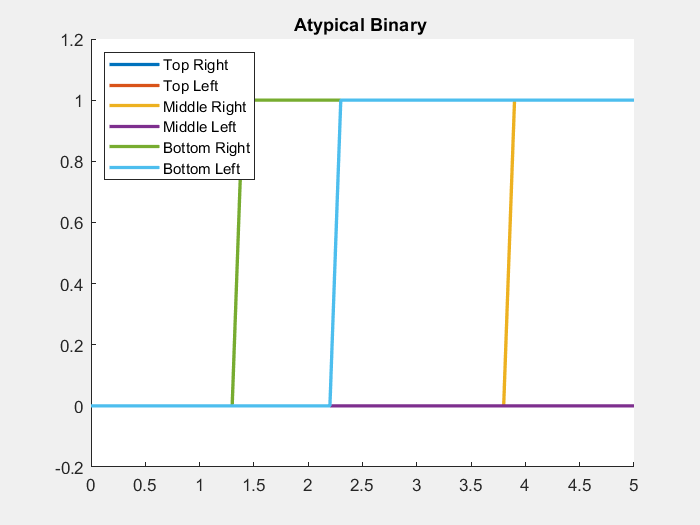

TH = 80;
TL2b=  TL2> TH;
TR2b = TR2 > TH;
ML2b = ML2 > TH;
MR2b = MR2 > TH;
BL2b = BL2 > TH;
BR2b = BR2 > TH;

%% load time series for simulink  %%
TL2bs=  timeseries(TL2b,ti);
TR2bs = timeseries(TR2b,ti);
ML2bs = timeseries(ML2b,ti);
MR2bs = timeseries(MR2b,ti);
BL2bs = timeseries(BL2b,ti);
BR2bs = timeseries(BR2b,ti);

figure(7)
set(gcf,'Name','Average Energy Through Time binary','Visible','on')
hold on;
plot(ti,TL2b,'LineWidth',2)
hold on;
plot(ti,TR2b,'LineWidth',2)
hold on;
plot(ti,ML2b,'LineWidth',2)
hold on;
plot(ti,MR2b,'LineWidth',2)
hold on;
plot(ti,BL2b,'LineWidth',2)
hold on;
plot(ti,BR2b,'LineWidth',2)
title("Atypical Binary ")
ylim([-0.2 1.2])
legend({'Top Right','Top Left','Middle Right','Middle Left','Bottom Right','Bottom Left'},'Location','northwest');

**MID**

[w,h,c,I] = size(A3_inter);
TL3 = [];
TR3 = [];
ML3 = [];
MR3 = [];
BL3 = [];
BR3 = [];
for i=1:1:I
    A_gray = rgb2gray(uint8(A3_inter(:,:,:,i)));
    TL3(:,end+1)=average_energy(A_gray(Y1:Y2,X1:X2));
    TR3(:,end+1)=average_energy(A_gray(Y3:Y4,X3:X4));
    ML3(:,end+1)=average_energy(A_gray(Y5:Y6,X5:X6));
    MR3(:,end+1)=average_energy(A_gray(Y7:Y8,X7:X8));
    BL3(:,end+1)=average_energy(A_gray(Y9:Y10,X9:X10));
    BR3(:,end+1)=average_energy(A_gray(Y11:Y12,X11:X12));
    
end

figure(8)
set(gcf,'Name','Average Energy Through Time','Visible','on')
hold on;
plot(ti,TL3)
hold on;
plot(ti,TR3)
hold on;
plot(ti,ML3)
hold on;
plot(ti,MR3)
hold on;
plot(ti,BL3)
hold on;
plot(ti,BR3)  
title("MID ")
legend({'Top Right','Top Left','Middle Right','Middle Left','Bottom Right','Bottom Left'},'Location','northwest');
TH = 80;
TL3b=  TL3> TH;
TR3b = TR3 > TH;
ML3b = ML3 > TH;
MR3b = MR3 > TH;
BL3b = BL3 > TH;
BR3b = BR3 > TH;

%% load time series for simulink  %%
TL3bs=  timeseries(TL3b,ti);
TR3bs = timeseries(TR3b,ti);
ML3bs = timeseries(ML3b,ti);
MR3bs = timeseries(MR3b,ti);
BL3bs = timeseries(BL3b,ti);
BR3bs = timeseries(BR3b,ti);

figure(9)
set(gcf,'Name','Average Energy Through Time binary','Visible','on')
hold on;
plot(ti,TL3b,'LineWidth',2)
hold on;
plot(ti,TR3b,'LineWidth',2)
hold on;
plot(ti,ML3b,'LineWidth',2)
hold on;
plot(ti,MR3b,'LineWidth',2)
hold on;
plot(ti,BL3b,'LineWidth',2)
hold on;
plot(ti,BR3b,'LineWidth',2)
title("MID Binary ")
ylim([-0.2 1.2])
legend({'Top Right','Top Left','Middle Right','Middle Left','Bottom Right','Bottom Left'},'Location','northwest');